# Final Project

**Yi-Chong Jiang, Aidan Strong, Eugene Hsue & Oscar Cheng**

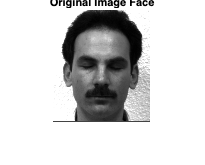

clear;clc;close all;



% Step Zero - Sample a random image from a folder 
SAMPLEDIR = 'AdjustedFaces';
SampleFaces=dir(SAMPLEDIR);
SampleFaces=SampleFaces(3:end);
randomInt = floor(rand*size(SampleFaces,1));
randomFile = SampleFaces(randomInt);


% Step one, load up all the face images
Files=dir('Faces');
Faces=Files(3:end);

% Getting the dimensions of the face
sampleImage = imread('Faces/subject01.glasses.pgm');
M = size(sampleImage,1);
N = size(sampleImage,2);

% Every directory has "." and ".." so we need to disregard those
FaceCount = length(Faces);

% Setup the average face vector
averageFace = zeros(M*N,1,'double');


% First we need to find the mean/average face
for k=1:FaceCount

   name = Faces(k).name;



   % Read the face, turn it into a double
   face = double(imread("Faces/"+name))/255;


   if k<15
       imwrite(face,"Output/"+k+".png")
   end

   % Turn it into a column
   columnFace = reshape(face,[],1);

   % Add it to the average face
   averageFace = averageFace + columnFace;
end

% Compute average face
averageFace = averageFace / FaceCount;

imwrite(reshape(averageFace,M,N),"Output/averageFace.png")

% Our total matrix of M*N vectors of face
totalFaceMatrix = zeros(M*N,FaceCount);

% Now take the difference from the average face and every other face, store
% it in a large face matrix
for k=1:FaceCount

   name = Faces(k).name;

   % Read the face, turn it into a double
   normalizedFace = double(imread("Faces/"+name))/255;

   % Turn it into a column
   columnFace = reshape(normalizedFace,[],1);

   % Construct the large face matrix by setting the whole column
   totalFaceMatrix(:,k) = averageFace-columnFace;

end


% Find the covariance matrix
covariance = transpose(totalFaceMatrix)*totalFaceMatrix;


% Find the eigenvalues (returns diagonal matrix D of generalized eigenvalues and 
% full matrix V whose columns are the corresponding right eigenvectors,  so that A*V = B*V*D.)
[eigenVectors,eigenValues] = eig(covariance);

% Sort the eigenvalues in descending order, keep track of how we sorted
% them
diagonal = diag(eigenValues);
[sortedEigenvalues,ind] = sort(abs(diagonal),'descend');
sortedEigenvectors = eigenVectors(:,ind);

% Get the K-Largest Eigenvalues
KLargestCount = 30;
eigenFaceVectors = zeros(KLargestCount,N*M);

for e=1: KLargestCount

    eigenface = sortedEigenvectors(:,e);
    displayEigenface = zeros(M,N,'double');

    % Vizualize the eigenface, this is purely aesthetic
    for k=1:FaceCount

        name = Faces(k).name;
        % Reread the file 
        face = double(imread("Faces/"+name))/255;
    
        % Add a linear combination
        displayEigenface = displayEigenface + eigenface(k)*face;

    end



    % Convert to a column
    eigenfaceColumn = reshape(displayEigenface,[],1);

    % Store it in a list
    eigenFaceVectors(e,:)=eigenfaceColumn;

end


% Get the dotted training faces
dottedTrainingFaces = zeros(KLargestCount,FaceCount);

for k=1:FaceCount
    tempFace = totalFaceMatrix(:,k);
    dottedTempFace = zeros(KLargestCount,1);
    for i=1:KLargestCount
        dottedTempFace(i) = dot(tempFace,eigenFaceVectors(i,:));
    end
    dottedTrainingFaces(:,k)=dottedTempFace;

end



% Actually process the random sample from up top
testFace = double(imread(SAMPLEDIR+"/"+randomFile.name));

% Normalize
testFace = testFace/255;

% Turn it into a column
columnTestFace = reshape(testFace,[],1);

% Subtract the face from the average face
subtractedTestFace = averageFace - columnTestFace;

% Dot product with all of our main eigenfaces
dottedInputFace = zeros(KLargestCount,1);
for i=1:KLargestCount
    dottedInputFace(i) = dot(subtractedTestFace,eigenFaceVectors(i,:));
end


figure

imshow(double(imread("Faces/"+Faces(randomInt).name))/255)
title('Original Image Face')

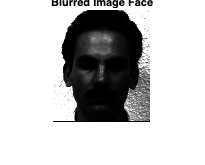

imwrite(double(imread("Faces/"+Faces(randomInt).name))/255,"Output/OriginalFace.png")
imshow(testFace);
title('Blurred Image Face')

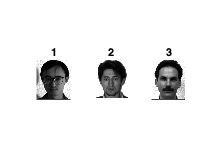

imwrite(testFace,"Output/AlteredFace.png")

% Get the top results
numResults = 3;
similarity = zeros(FaceCount);
for i=1:FaceCount

    dist = norm(dottedInputFace-dottedTrainingFaces(:,i));
    similarity(i)=dist;
end
[indices,ordering] = sort(similarity,'ascend');

offset = 0;
% Display the closest face
for i=1:numResults+1

    % Make sure we don't include the face that we're testing
    if ordering(i) == randomInt
        offset=offset+1;
        continue
    end

    name = Faces(ordering(i)).name;

    % Read the face, turn it into a double
    face = double(imread("Faces/"+name))/255;
    subplot(1,3,i-offset);
    imshow(face);
    title(string(i-offset))
    imwrite(face,"Output/Guess"+string(i-offset)+".png")
end